## Week 10

### netCDF Files and Format

Next let us talk about netCDF. Visit here: [http://www.unidata.ucar.edu/software/netcdf/.](http://www.unidata.ucar.edu/software/netcdf) This is a very popular data format in many different scientific fieds. Some key features include:

-  Self-describing. A netCDF file contains information about the data, or metadata. This is HUGE...we have previously worke with simple text files (remember the USGS data) that had long headers describing the source of the data, the format of the data, the units of the variables and so on. That is a fine way to go. The WORST thing is a spreadsheet with columns of numbers and no documentation. A netCDF file is a binary file, so you can't open it and see it in a text editor, but it is easy to open the file and see the contents with a variety of program.

- Portable. Can be accessed by computers with different ways of storing numbers 

- Scalable. Small subsets of large data files can be easily accessed. 

- Appendable. Data can be added without having to copy / redefine data structure. 

- Sharable. Many people can access at same time

### Reading netCDF

I have included a file (sample.nc) with this week's notes. Let's first get a little information about this file:

clear all
close all
home

%use finfo to get basic information about a file
finfo=ncinfo('sample.nc')

finfo = struct with fields:
      Filename: '/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10/sample.nc'
          Name: '/'
    Dimensions: [1×4 struct]
     Variables: [1×7 struct]
    Attributes: [1×13 struct]
        Groups: []
        Format: 'classic'
     Datatypes: []


Ok. That's pretty brief. But there is a huge amount going on. We have a structure that has fields like Dimensions, Variables, Attributes and so on. Let's dig a bit deeper. The 'attributes' typically refers to global characteristics of the dataset. The who / what / why sort of thing.

%We can look at the attributes of the data stored in the file
finfo.Attributes

ans = 1×13 struct array with fields:
    Name
    Value



%Each attribute can have a name. Let's just look at the first one
finfo.Attributes(1).Name

ans = 'title'


%Ok, well now we can look at the 'value' for this 'name.'
finfo.Attributes(1).Value

ans = 'IPSL  model output prepared for IPCC Fourth Assessment SRES A2 experiment'

Next, let's poke around in the 'variables' part of the data file.

finfo.Variables

ans = 1×7 struct array with fields:
    Name
    Dimensions
    Size
    Datatype
    Attributes
    ChunkSize
    FillValue
    DeflateLevel
    Shuffle



%Let's look at some of the data
disp('Name, dimensions, and size of first variable')

Name, dimensions, and size of first variable


finfo.Variables(1).Name

ans = 'lon'

finfo.Variables(1).Dimensions

ans = struct with fields:
         Name: 'lon'
       Length: 180
    Unlimited: 0


finfo.Variables(1).Size  %num of lon values.

ans = 180

disp(' ')

disp('Name, dimensions, and size of last variable')

Name and size of last variable


finfo.Variables(end).Name

ans = 'tos'

finfo.Variables(end).Dimensions

ans = 1×3 struct array with fields:
    Name
    Length
    Unlimited


finfo.Variables(end).Size %num of tos values (hourly values for one day).

ans =    180   170    24


%So, it is beginning to look like we have gridded data on a lon / lat grid.
pause
home

So. This is a touch confusing at first glance. We have a variable called 'lon' (short for longitude). This variable has a 'dimension'. And this dimension is also called 'lon' and we see that it has a length of 180. So, every variable is a netCDF file must have a 'name' and also a 'dimension.' 

If you now look at the last variable printed out (tos - temperature of the ocean surface), you see that it has a name (tos), it has a size (180 x 170 x 24) and it has the dimensions of lon, lat, and time. So, that 3d cube of data represents 24 time slices of data on a rectangular grid defined by longitude and latitude limits. The first variable printed out (lon) has a name (lon), it has a size (180) and it it defined on a vector defined by the longitude limits. 

So, it may initially feel confusing to deal with this 'dimensions field' but think about it in terms of what that represents. If you have a vector of numbers in your data file, what defines the span of that vector?? Often it is time (data collected by a sensor over a certain time period). Other times it is space (some extent of span of the world) and so on.

Great. Well, now lets us actually read in some data. We will read in the entire data file and then plot one of the time slices.

%lets access some data with ncread and plot it
lon=ncread('sample.nc','lon');
lat=ncread('sample.nc','lat');
tos=ncread('sample.nc','tos');
size(tos)

ans =    180   170    24


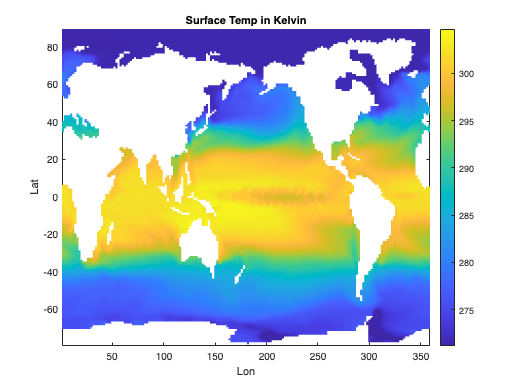


pcolor(lon,lat,tos(:,:,1)'); shading flat
colorbar
xlabel('Lon');ylabel('Lat');title('Surface Temp in Kelvin')


%pretty slick...everything you need re: this dataset is packaged up really
%nicely with full metadata and description. THAT is the way to curate your
%data.

Can we choose to read in just a portion of the dataset to reduce memory demands? Yep. Below I will read in ONLY the first time slice and only for (roughly) North America.

%lets access some data with ncread and plot it
lon=ncread('sample.nc','lon',91,90);
lat=ncread('sample.nc','lat',86,85);
tos=ncread('sample.nc','tos',[91 86 1],[90 85 1]);
size(tos)

ans =     90    85


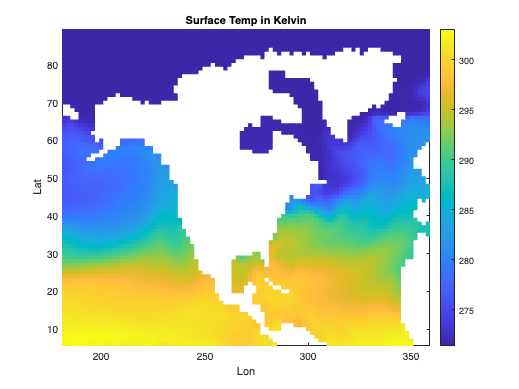


pcolor(lon,lat,tos'); shading flat
colorbar
xlabel('Lon');ylabel('Lat');title('Surface Temp in Kelvin')

### Writing netCDF

We can also create netCDF files in matlab. Regardless of whether you use netCDF or another file format, it is worth being careful about describing your data. This brings up the general topic of METADATA.

Have a look at [https://en.wikipedia.org/wiki/Metadata_standard](https://en.wikipedia.org/wiki/Metadata_standard)

There are many standards, depending on your field. And, things can get mighty confusing! A good place to start is here: [https://www.usgs.gov/data-management/metadata-creation](https://www.usgs.gov/data-management/metadata-creation)

One decent standard is FGDC-CSDGM, which stands for 'Federal Geographic Data Committee' and 'Content Standard for Digital Geospatial Metadata'. At the link immediately above, you will find, among other things, tools for creating metadata files. 

For example, you can go [here](https://doi-usgs.github.io/fort-pymdwizard/) and download a windows / mac version of software that will help you create metadata files. 

You can also go here: [https://www.mdeditor.org/](https://www.mdeditor.org/) and use an 'online' tool for creating metadata files. Basically, you will be prompted to enter information about your dataset via a number of dialog boxes and it will produce a working metadata file for you.

Next, it is not always the case that you will follow 'strict' metadata standards. Often times, creating a good 'readme' file will suffice. Please see [http://data.research.cornell.edu/content/readme](http://data.research.cornell.edu/content/readme) for a great overview. This can be a simple text file that you include with each data file that you create. If you work in ASCII files, you can write all the metadata into the header. With netCDF, it can be written into the 'attributes' of the file.

Let's do a little experiment by creating some fake data and then writing it to a netCDF file.

clear all
clc

%these next two lines basically allow us to overwrite the file if it
%already exists. Generally, there are tight controls in place that prevent
%this type of overwriting. Which is a good thing!

ncid=netcdf.create('testfile.nc','CLOBBER');
netcdf.close(ncid);

days=[1:365]';  %days of year, 2016
data=randn(365,1);  %fake data, who cares

nccreate('testfile.nc','time','Dimensions',{'t',length(days)});
ncwrite('testfile.nc','time',days);

nccreate('testfile.nc','temp','Dimensions',{'t',length(data)});
ncwrite('testfile.nc','temp',data);

%lets write in some attributes about the variables
ncwriteatt('testfile.nc','time','long_name','Julian Days');
ncwriteatt('testfile.nc','time','units','Days since 1 Jan 2016');
ncwriteatt('testfile.nc','temp','long_name','Temperature');
ncwriteatt('testfile.nc','temp','units','deg C');

%lets write in some global attributes
ncwriteatt('testfile.nc','/','creation_date',datestr(now));
ncwriteatt('testfile.nc','/','creator','David Hill');
ncwriteatt('testfile.nc','/','description','Temperature data at Corvallis, Oregon');
disp('We have now written our file.')

We have now written our file.


That's it. The file has now been written! Don't belive it? Let's check.

%You can use the ncdisp command to show the metadata
home
ncdisp('testfile.nc')

Source:
           /Users/dfh/Documents/MATLAB/testfile.nc
Format:
           classic
Global Attributes:
           creation_date = '29-Nov-2023 14:01:54'
           creator       = 'David Hill'
           description   = 'Temperature data at Corvallis, Oregon'
Dimensions:
           t = 365
Variables:
    time
           Size:       365x1
           Dimensions: t
           Datatype:   double
           Attributes:
                       long_name = 'Julian Days'
                       units     = 'Days since 1 Jan 2016'
    temp
           Size:       365x1
           Dimensions: t
           Datatype:   double
           Attributes:
                       long_name = 'Temperature'
                       units     = 'deg C'


%You can use the ncinfo command to access information. For example

finfo=ncinfo('testfile.nc')

finfo = struct with fields:
      Filename: '/Users/dfh/Documents/MATLAB/testfile.nc'
          Name: '/'
    Dimensions: [1×1 struct]
     Variables: [1×2 struct]
    Attributes: [1×3 struct]
        Groups: []
        Format: 'classic'
     Datatypes: []


variablename1=finfo.Variables(1).Name

variablename1 = 'time'

variablename2=finfo.Variables(2).Name

variablename2 = 'temp'

numpoints=finfo.Variables(1).Size

numpoints = 365

So, let us now re-read the data that we just wrote, and make a plot.

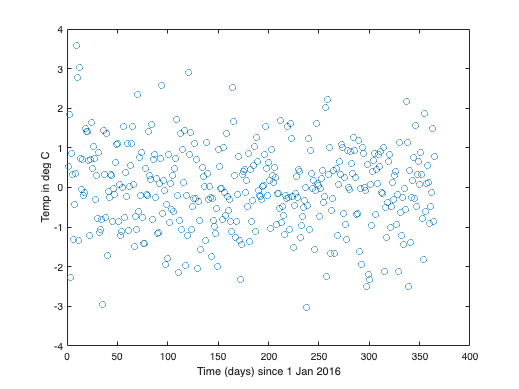

TIME=ncread('testfile.nc',variablename1);
TEMP=ncread('testfile.nc',variablename2);
figure(1)
plot(TIME,TEMP,'o');xlabel('Time (days) since 1 Jan 2016');
ylabel('Temp in deg C');

so...the bottom line is this...it takes time and effort to write good data files. It is suuuuper tempting to neglect this aspect of your scientific work. In the short-term, it might work out ok for you, in terms of producing results and figures quickly. In the long-term, you will massively regret it. So, budget your time and ensure that you write good, well documented data files. The same goes for good, well documented codes.